
[x]=importdata('required/listx.txt');

[y]=importdata('required/listy.txt');

[z]=importdata('required/listz.txt');

%[LATGRID,LONGRID]=meshgrid(latGRID,lonGRID)d
%}
% Punto inicial 39.020594, -0.211071
% Punto final 38.944588, -0.129491

% Dividimos la lat/lon inicial hasta la lat/lon final de 20*n en 20*n
% metros.
y1 = 38.944588:(0.00018*1):39.020594; 
x1= -0.211071:(0.00023*1):-0.129491;


[X1,Y1] = meshgrid(x1,y1);


[X1,Y1] = meshgrid(x1,y1);

writematrix(X1,"fixedx.txt",'Delimiter',',') 
writematrix(Y1,"fixedy.txt",'Delimiter',',') 

Z_corrector= griddata(x,y,z,X1,Y1,'v4');

Z_corrector = max(0,min(100,Z_corrector))

Z_corrector =     0.0000    0.0130    0.0259    0.0389    0.0520    0.0652    0.0786    0.0922    0.1060    0.1200    0.1342    0.1487    0.1635    0.1785    0.1938    0.2094    0.2252    0.2414    0.2579    0.2747    0.2918    0.3092    0.3270    0.3451    0.3635    0.3823    0.4014    0.4209    0.4407    0.4608    0.4813    0.5022    0.5234    0.5449    0.5669    0.5891    0.6118    0.6348    0.6581    0.6818    0.7059    0.7303    0.7550    0.7802    0.8057    0.8315    0.8577    0.8842    0.9111    0.9383
         0         0         0    0.0020    0.0152    0.0286    0.0422    0.0559    0.0699    0.0840    0.0985    0.1131    0.1280    0.1432    0.1587    0.1745    0.1906    0.2069    0.2236    0.2406    0.2579    0.2756    0.2936    0.3119    0.3305    0.3495    0.3689    0.3886    0.4086    0.4290    0.4497    0.4708    0.4923    0.5141    0.5363    0.5588    0.5817    0.6050    0.6286    0.6526    0.6769    0.7016    0.7267    0.7521    0.7779    0.8041    0.8306    0.8574    0


max(max(Z_corrector))

ans = 63.7761


cosa = pcolor(X1,Y1,Z_corrector), shading interp, colorbar;

cosa =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [423×355 double]
           YData: [423×355 double]
           ZData: [423×355 double]
           CData: [423×355 double]

  Show all properties


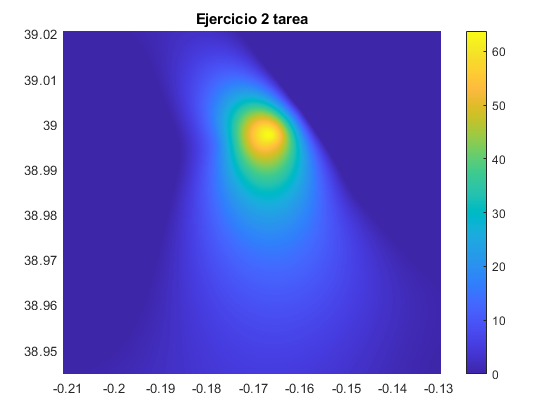

 
%cosa.saveFig()

% plot(Z_corrector)
title('Ejercicio 2 tarea')


% figure, [C,h]=contour(X1,Y1,LDEN_corrector, 30); clabel(C,h),colorbar
% title('Curvas de nivel tarea 2')
%writematrix(Z_corrector,'result.txt','Delimiter',',')  
